## **AAE340 HW8 PROBLEM 4    **

clear all
close all
clc

## <4b>

% Solving the differential equation using ode45 
% Drag coefficient = 0.01 
C_d1 = 0.01;  % Drag coefficient
tspan1 = 0:0.0001:60;  % Time interval
IC1 = [0, 0];  % Initial conditions 
options = odeset('RelTol',1e-12, 'AbsTol',1e-12);  % ode45 options 
[t1, x1] = ode45(@(t,x) dfq(t, x, C_d1), tspan1, IC1, options);
x1_pos = x1(:,1);  % The position vector
x1_vel = x1(:,2);  % The velocity vector
temp = x1_pos;  % Holding the vector of the positions 
x1_pos(temp<0) = [];  % Removing the position values smaller than 0 and reshaping the vector 
x1_vel(temp<0) = [];  % Same as above
t1(temp<0) = [];  % Same as above
[maxAlt1, maxIdx1] = max(x1_pos);  % Obtaining the maximum altitude and corresponding index
maxT1 = t1(maxIdx1);  % Corresponding time of above

% Drag coefficient = 0.1 
C_d2 = 0.1;  % Drag coefficient
tspan2 = 0:0.0001:60;  % Time interval
IC2 = [0, 0];  % Initial conditions 
options = odeset('RelTol',1e-12, 'AbsTol',1e-12);  % ode45 options 
[t2, x2] = ode45(@(t,x) dfq(t, x, C_d2), tspan2, IC2, options);
x2_pos = x2(:,1);  % The position vector
x2_vel = x2(:,2);  % The velocity vector
temp = x2_pos;  % Holding the vector of the positions 
x2_pos(temp<0) = [];  % Removing the position values smaller than 0 and reshaping the vector 
x2_vel(temp<0) = [];  % Same as above
t2(temp<0) = [];  % Same as above
[maxAlt2, maxIdx2] = max(x2_pos);  % Obtaining the maximum altitude and corresponding index
maxT2 = t2(maxIdx2);  % Corresponding time of above

% Drag coefficient = 1
C_d3 = 1.0;  % Drag coefficient 
tspan3 = 0:0.0001:60;  % Time interval 
IC3 = [0, 0];  % Intial conditions 
options = odeset('RelTol',1e-12, 'AbsTol',1e-12);  % ode45 options 
[t3, x3] = ode45(@(t,x) dfq(t,x,C_d3), tspan3, IC3, options);
x3_pos = x3(:,1);  % The position vector
x3_vel = x3(:,2);  % The velocity vector
temp = x3_pos;  % Holding the vector of positions 
x3_pos(temp<0) = [];  % Removing the position values smaller than 0 and reshaping the vector
x3_vel(temp<0) = [];  % Same as above
t3(temp<0) = [];  % Same as above
[maxAlt3, maxIdx3] = max(x3_pos);  % Obtaining the maximum altitude and corresponding index
maxT3 = t3(maxIdx3);  % Corresponding time of above

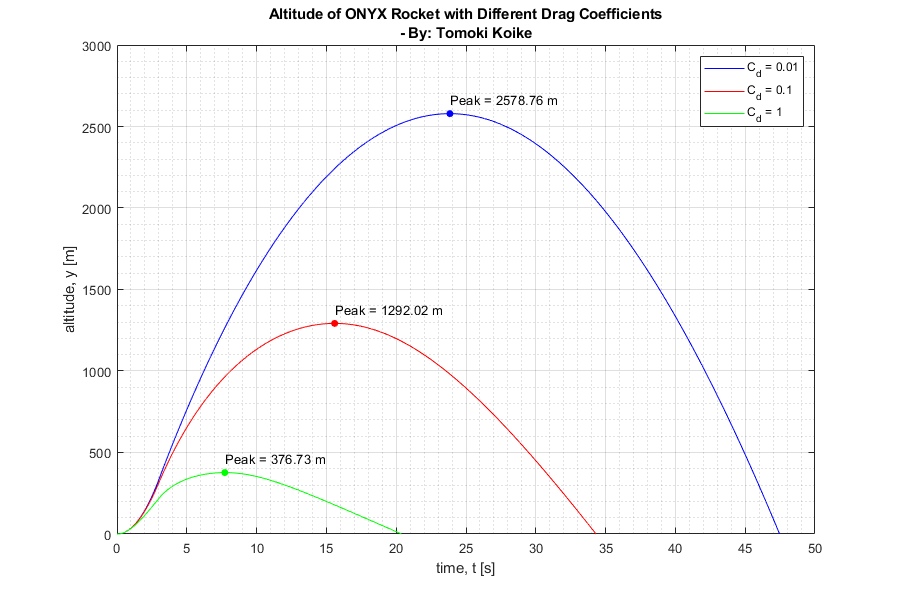

% Plotting 
figure('Renderer', 'painters', 'Position', [10 10 900 600])
plot(t1, x1_pos, '-b')
xlabel('time, t [s]')
ylabel('altitude, y [m]')
title({'Altitude of ONYX Rocket with Different Drag Coefficients', ['-' ...
    ' By: Tomoki Koike']})
hold on
plot(t2, x2_pos, '-r')
plot(t3, x3_pos, '-g')
plot(maxT1, maxAlt1, '.b', 'MarkerSize',18)
plot(maxT2, maxAlt2, '.r', 'MarkerSize',18)
plot(maxT3, maxAlt3, '.g', 'MarkerSize',18)
hold off
grid on 
grid minor
box on
legend('C_d = 0.01', 'C_d = 0.1', 'C_d = 1')
txtFormat = 'Peak = %.2f m';
txt1 = sprintf(txtFormat, maxAlt1);
text(maxT1,maxAlt1+90,txt1,'HorizontalAlignment','left')
txt2 = sprintf(txtFormat, maxAlt2);
text(maxT2,maxAlt2+90,txt2,'HorizontalAlignment','left')
txt3 = sprintf(txtFormat, maxAlt3);
text(maxT3,maxAlt3+90,txt3,'HorizontalAlignment','left')

## <4c>

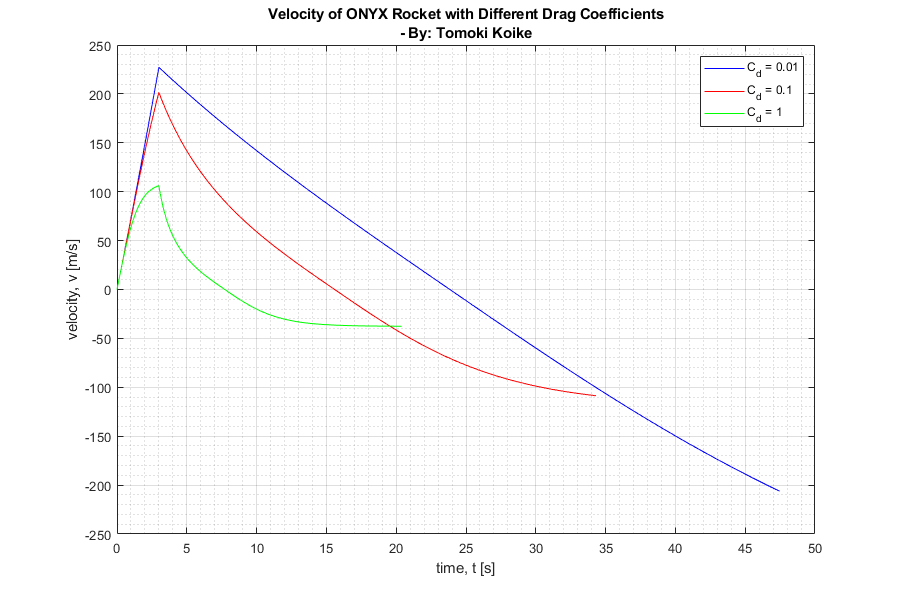

% Plotting 
figure('Renderer', 'painters', 'Position', [10 10 900 600])
plot(t1, x1_vel, '-b')
xlabel('time, t [s]')
ylabel('velocity, v [m/s]')
title({'Velocity of ONYX Rocket with Different Drag Coefficients', ['-' ...
    ' By: Tomoki Koike']})
hold on
plot(t2, x2_vel, '-r')
plot(t3, x3_vel, '-g')
hold off
grid on 
grid minor
box on
legend('C_d = 0.01', 'C_d = 0.1', 'C_d = 1')

## <4d>

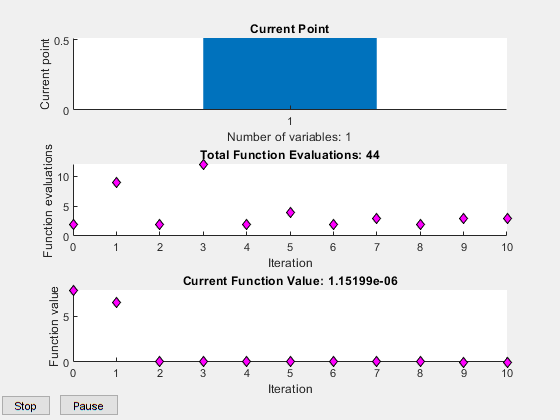

% Find the drag coefficient that gives us the advertised max altitude 
figure('Renderer', 'painters', 'Position', [10 10 900 600])
[x,fval,exitflag,output,lambda,grad,hessian] = optC_d(0.5,0.3,1.26);

Cd_find = vpa(x,10);


tspan4 = 0:0.0001:25;  % Time interval 
IC4 = [0, 0];  % Intial conditions 
options = odeset('RelTol',1e-12, 'AbsTol',1e-12);  % ode45 options 
[t4, x4] = ode45(@(t,x) dfq(t,x,Cd_find), tspan3, IC4, options);
x4_pos = x4(:,1);  % The position vector
x4_vel = x4(:,2);  % The velocity vector
temp = x4_pos;  % Holding the vector of positions 
x4_pos(temp<0) = [];  % Removing the position values smaller than 0 and reshaping the vector
x4_vel(temp<0) = [];  % Same as above
t4(temp<0) = [];  % Same as above
[maxAlt4, maxIdx4] = max(x4_pos);  % Obtaining the maximum altitude and corresponding index
maxT4 = t4(maxIdx4);  % Corresponding time of above

fprintf(['The drag coefficient corresponding to the advertised altitude of %.2f m' ...
    ': %.7f'], maxAlt4, Cd_find);

The drag coefficient corresponding to the advertised altitude of 548.64 m: 0.5128061

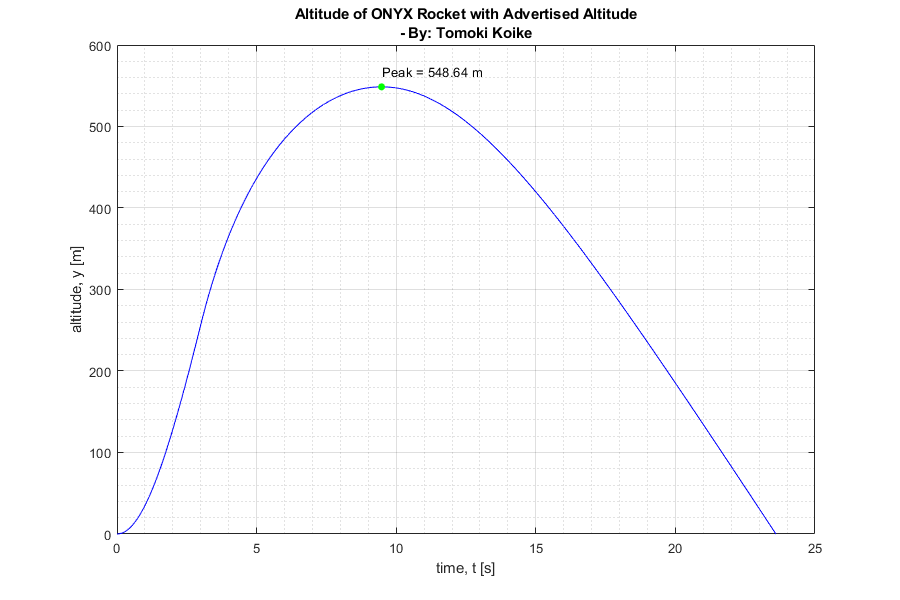


% Plotting
figure('Renderer', 'painters', 'Position', [10 10 900 600])
plot(t4, x4_pos, '-b')
xlabel('time, t [s]')
ylabel('altitude, y [m]')
title({'Altitude of ONYX Rocket with Advertised Altitude', ['-' ...
    ' By: Tomoki Koike']})
hold on
plot(maxT4, maxAlt4, '.g', 'MarkerSize',18)
hold off
grid on 
grid minor
box on
txt4 = sprintf(txtFormat, maxAlt4);
text(maxT4,maxAlt4+20,txt4,'HorizontalAlignment','left')

## FUNCTION

function dxdt = dfq(t, x, C_d)
    % Defining constants
    m_e = 0.368544;  % Empty mass of the rocket [kg]
    m_motor = 0.125;  % Mass of the motor [kg]
    m0 = m_e + m_motor;  % Overall mass [kg]
    t_b = 3.0;  % Burn time [s]
    T = 40.0;  % Thrust [N]
    m_prop = 0.0625;  % Mass of the propellant [kg]
    m_prop_dot = m_prop / t_b;  % Mass flow rate of the propellant [kg/s]
    rho = 1.225;  % Density of air [kg/m^3]
    D = 0.07874;  % Diameter of the rocket [m]
    A = pi * (D/2)^2;  % Cross-sectional area of the rocket [m^2]
    drag = 0.5 * rho * A * C_d;  % Drag term without the velocity squared timed to it yet
    g = 9.80665;  % Gravitational acceleration [m/s^2]
    
    dxdt = zeros(2, 1);  % Preallocating the derivative terms vector
    dxdt(1) = x(2);  % State variable of y_dot
    if t <= t_b
        % State variable of y_double_dot when thruster is on
        m_t = m0 - m_prop_dot*t;
    else 
        % State variable of y_double_dot when thruster is not on
        m_t = m0 - m_prop;
        T = 0;
    end
    dxdt(2) = T/m_t - drag*(x(2))^2*sign(x(2)) / (m_t) - g;
end

% Optimization Objective function
function obj = myObj(C_d)
    tspan = 0:0.0001:25;  % Time interval
    options = odeset('RelTol',1e-12, 'AbsTol',1e-12);  % ode45 options 
    [time, xs] = ode45(@(t,x) dfq(t, x, C_d), tspan, [0,0], options);
    obj = abs(max(xs(:,1))-548.64);
end

% Optimization fmincon function 
function [x,fval,exitflag,output,lambda,grad,hessian] = optC_d(x0,lb,ub)   
    %% Start with the default options
    options = optimoptions('fmincon');
    %% Modify options setting
    options = optimoptions(options,'Display', 'off');
    options = optimoptions(options,'PlotFcn', {  @optimplotx @optimplotfunccount @optimplotfval });
    [x,fval,exitflag,output,lambda,grad,hessian] = ...
    fmincon(@myObj,x0,[],[],[],[],lb,ub,[],options);
end